# Chapter 3 Exercises - Solutions

#### Exercise 3.3

syms a11 a12 a21 a22 b1 b2 c1 c2

% Calculate c coefficients
c = solve(P(2) - P(1))

$$c = \left(\begin{array}{c} \frac{1}{3}\\ 1 \end{array}\right)$$

c1 = c(1);
c2 = c(2);

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = b1 * c1 + b2 == 1/2;
eq3 = b1 * c1 ^ 2 + b2 == 1/3;
eq3 = a11 + a12 == c1;
eq4 = a21 + a22 == 1;
eq5 = a11 * c1 + a12 * c2 == 1/2 * c1^2;
eq6 = a21 * c1 + a22 * c2 == 1/2;

% Solve order conditions
solve(eq1, eq2, eq3, eq4, eq5, eq6)

ans = struct with fields:
    a11: 5/12
    a12: -1/12
    a21: 3/4
    a22: 1/4
     b1: 3/4
     b2: 1/4


#### Exercise 3.4

`C`alculate the first step of the third-order Radau IIA method derived in exercise 16 to solve the following initial value problem using a step length of $h=0.4$ and a accuracy tolerance of $tol = 10^{-4}$


$$y' =t - y, \qquad t \in [0,2], \qquad y(0) = 1.$$


The exact solution to this initial value problem is $y = t + 2e^{-t} - 1$. Produce a table comparing the numerical and exact solutions and plot the numerical solutions and exact solutions on the same set of axes.

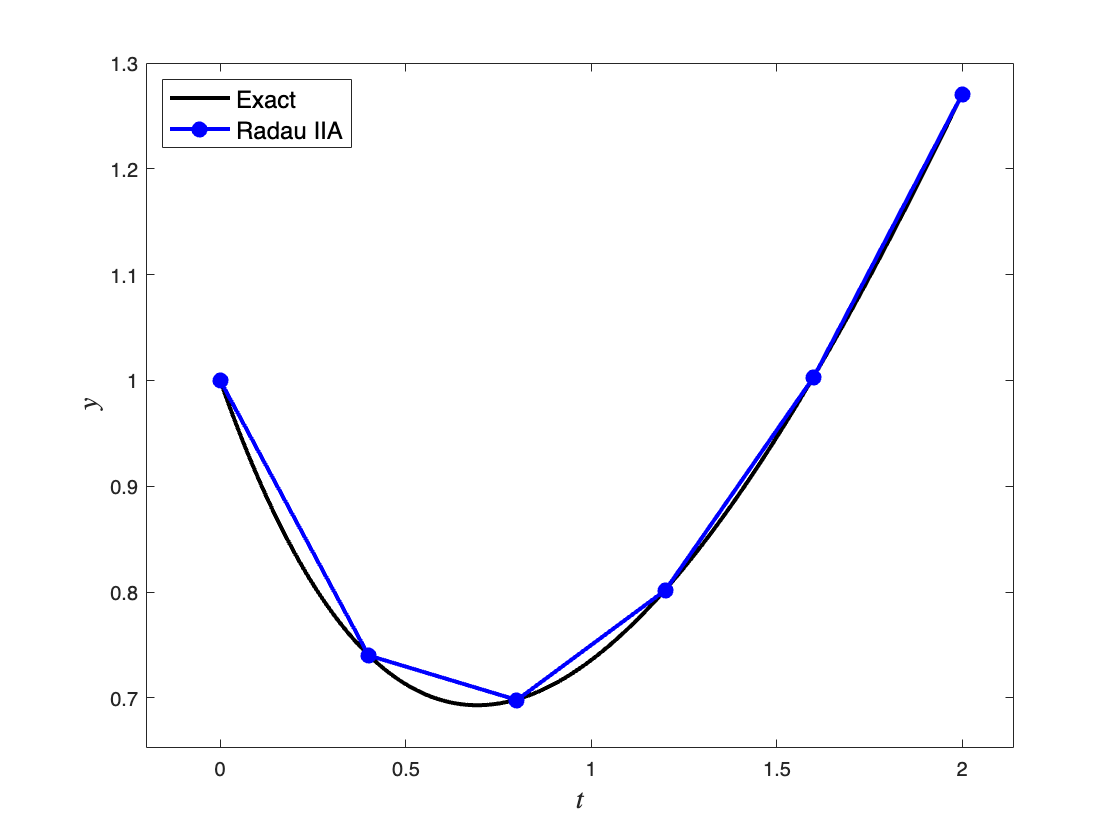

% Define ODE function and exact solution
f = @(t, y) t - y;
exact = @(t) t + 2 * exp(-t) - 1;

% Define IVP parameters
tspan = [0, 2];     % boundaries of the t domain
y0 = 1;             % initial value of the solution
h = 0.4;            % step length
tol = 1e-4;         % accuracy tolerance

% Calculate the solution to the IVP
[t, y] = solveIVP(f, tspan, y0, h, @radauIIA);

% Calculate exact solution for plotting
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Plot solution
plot(texact, yexact, 'k-', LineWidth=2)
hold on
plot(t, y, 'b-o', LineWidth=2, MarkerFaceColor='b')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'Radau IIA', Location='northwest', FontSize=12)

## Functions

#### Legendre polynomial

function Pn = P(n)

syms x
Pn = 0;
for k = 0 : n
    Pn = Pn + nchoosek(n, k) * nchoosek(n + k, k) * (x - 1) ^ k;
end

end

#### Single step solver

function [t, y] = solveIVP(f, tspan, y0, h, solver)

% Define t and y arrays
t = (tspan(1) : h : tspan(2));
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Loop through the steps and calculate single step solver solution
for n = 1 : length(t) - 1
    y(n+1,:) = solver(f, t(n), y(n,:), h);
end

end

#### Radau IIA method

function ynew = radauIIA(f, t, y, h)

neq = length(y);
Y1 = ones(neq);
Y2 = ones(neq);
Y1old = ones(neq);
Y2old = ones(neq);
for k = 1 : 10
    Y1 = y + h * (5/12 * f(t + 1/3 * h, Y1) - 1/12 * f(t + h, Y2));
    Y2 = y + h * (3/4 * f(t + 1/3 * h, Y1) + 1/4 * f(t + h, Y2));
    if max(max(abs(Y1 - Y1old)), max(abs(Y2 - Y2old))) < 1e-4
        break
    end
    Y1old = Y1;
    Y2old = Y2;
end
ynew = y + h / 4 * (3 * f(t + 1/3 * h, Y1) + f(t + h, Y2));

end